dataIn = audioClipObj.getCurrentVec   ;
defined_filter = define_a_filter(5,4.95);

% dataIn = bandpass(dataIn,[40000,90000],250000,'Steepness',1);


features =  extract(defined_filter,dataIn);

    
    %Normlize and smooth
    unNorm = 2/(sum(defined_filter.Window)^2);
    features = features/unNorm;
    epsil = 1e-14;
    

    
    features = log10(features + epsil);

 image_width = 51;
 sequenceLength = size(features,1);
 sequenceOverlap = 0;
 
    [featuresCell,~]=feature_matrix_to_images(...
                         features,...
                         [],...
        image_width,sequenceLength,sequenceOverlap);


[I,act1_t,numFilters, numTimes] = getFilteredMap(net, featuresCell, 'conv_a1');

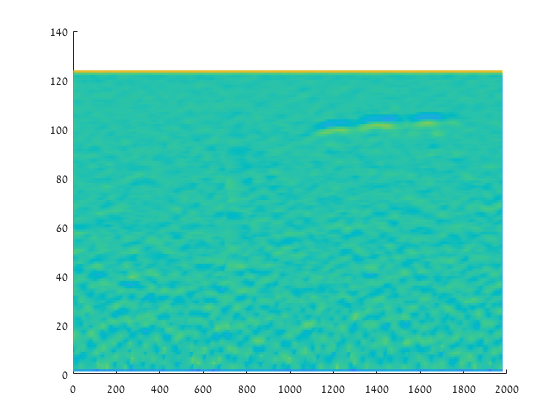

clf;
n = 2;

bans = 124;
inds = (1+(n-1)*bans):(n*bans);
Iin = I(inds,:);
surface(Iin,'EdgeColor','none')
colormap default

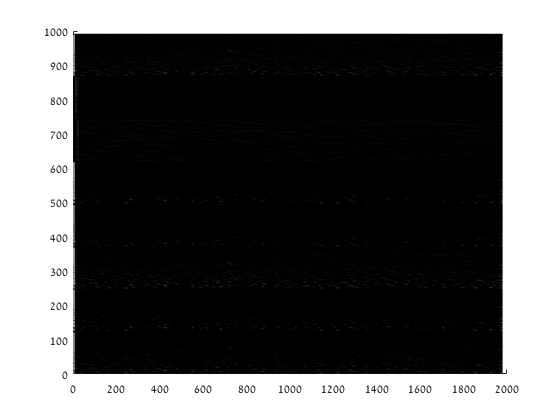

clf
[I,act1_t] = getFilteredMap(net, featuresCell, 'relu_1_3');
surface(I,'EdgeColor','none')
colormap gray